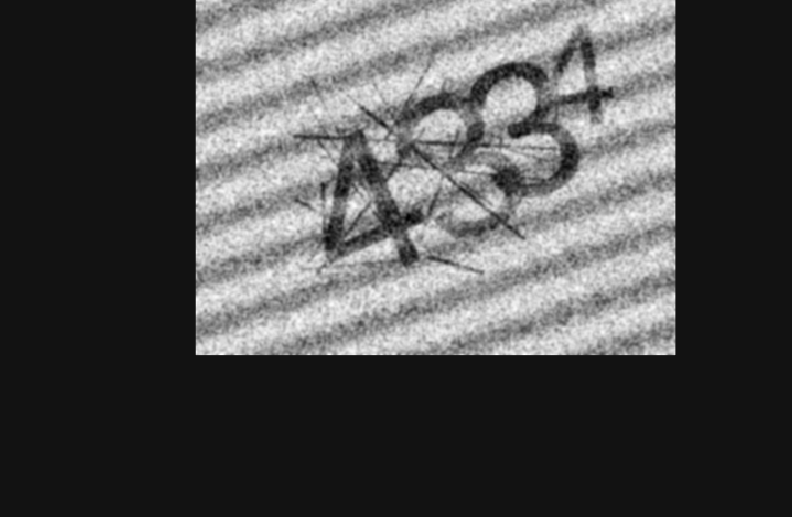

I = imread("C:\UPPSALA 2025\INTRODUCTION TO IMAGE ANALYSIS\Intro2IA_Mini_Project_complete\Train\captcha_0001.png");
Ig = im2double(rgb2gray(I));

figure; imshow(Ig,[]); title("Original grayscale");

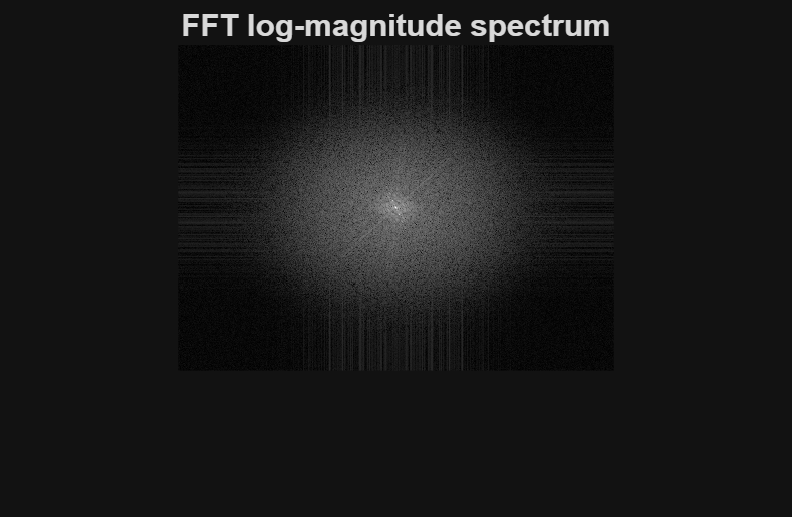

F = fft2(Ig);
Fshift = fftshift(F);

spec = log(1 + abs(Fshift));

figure; imshow(mat2gray(spec),[]); title("FFT log-magnitude spectrum");

disp("Click on BRIGHT PEAKS in the spectrum (other than center). Press ENTER when done.");

Click on BRIGHT PEAKS in the spectrum (other than center). Press ENTER when done.


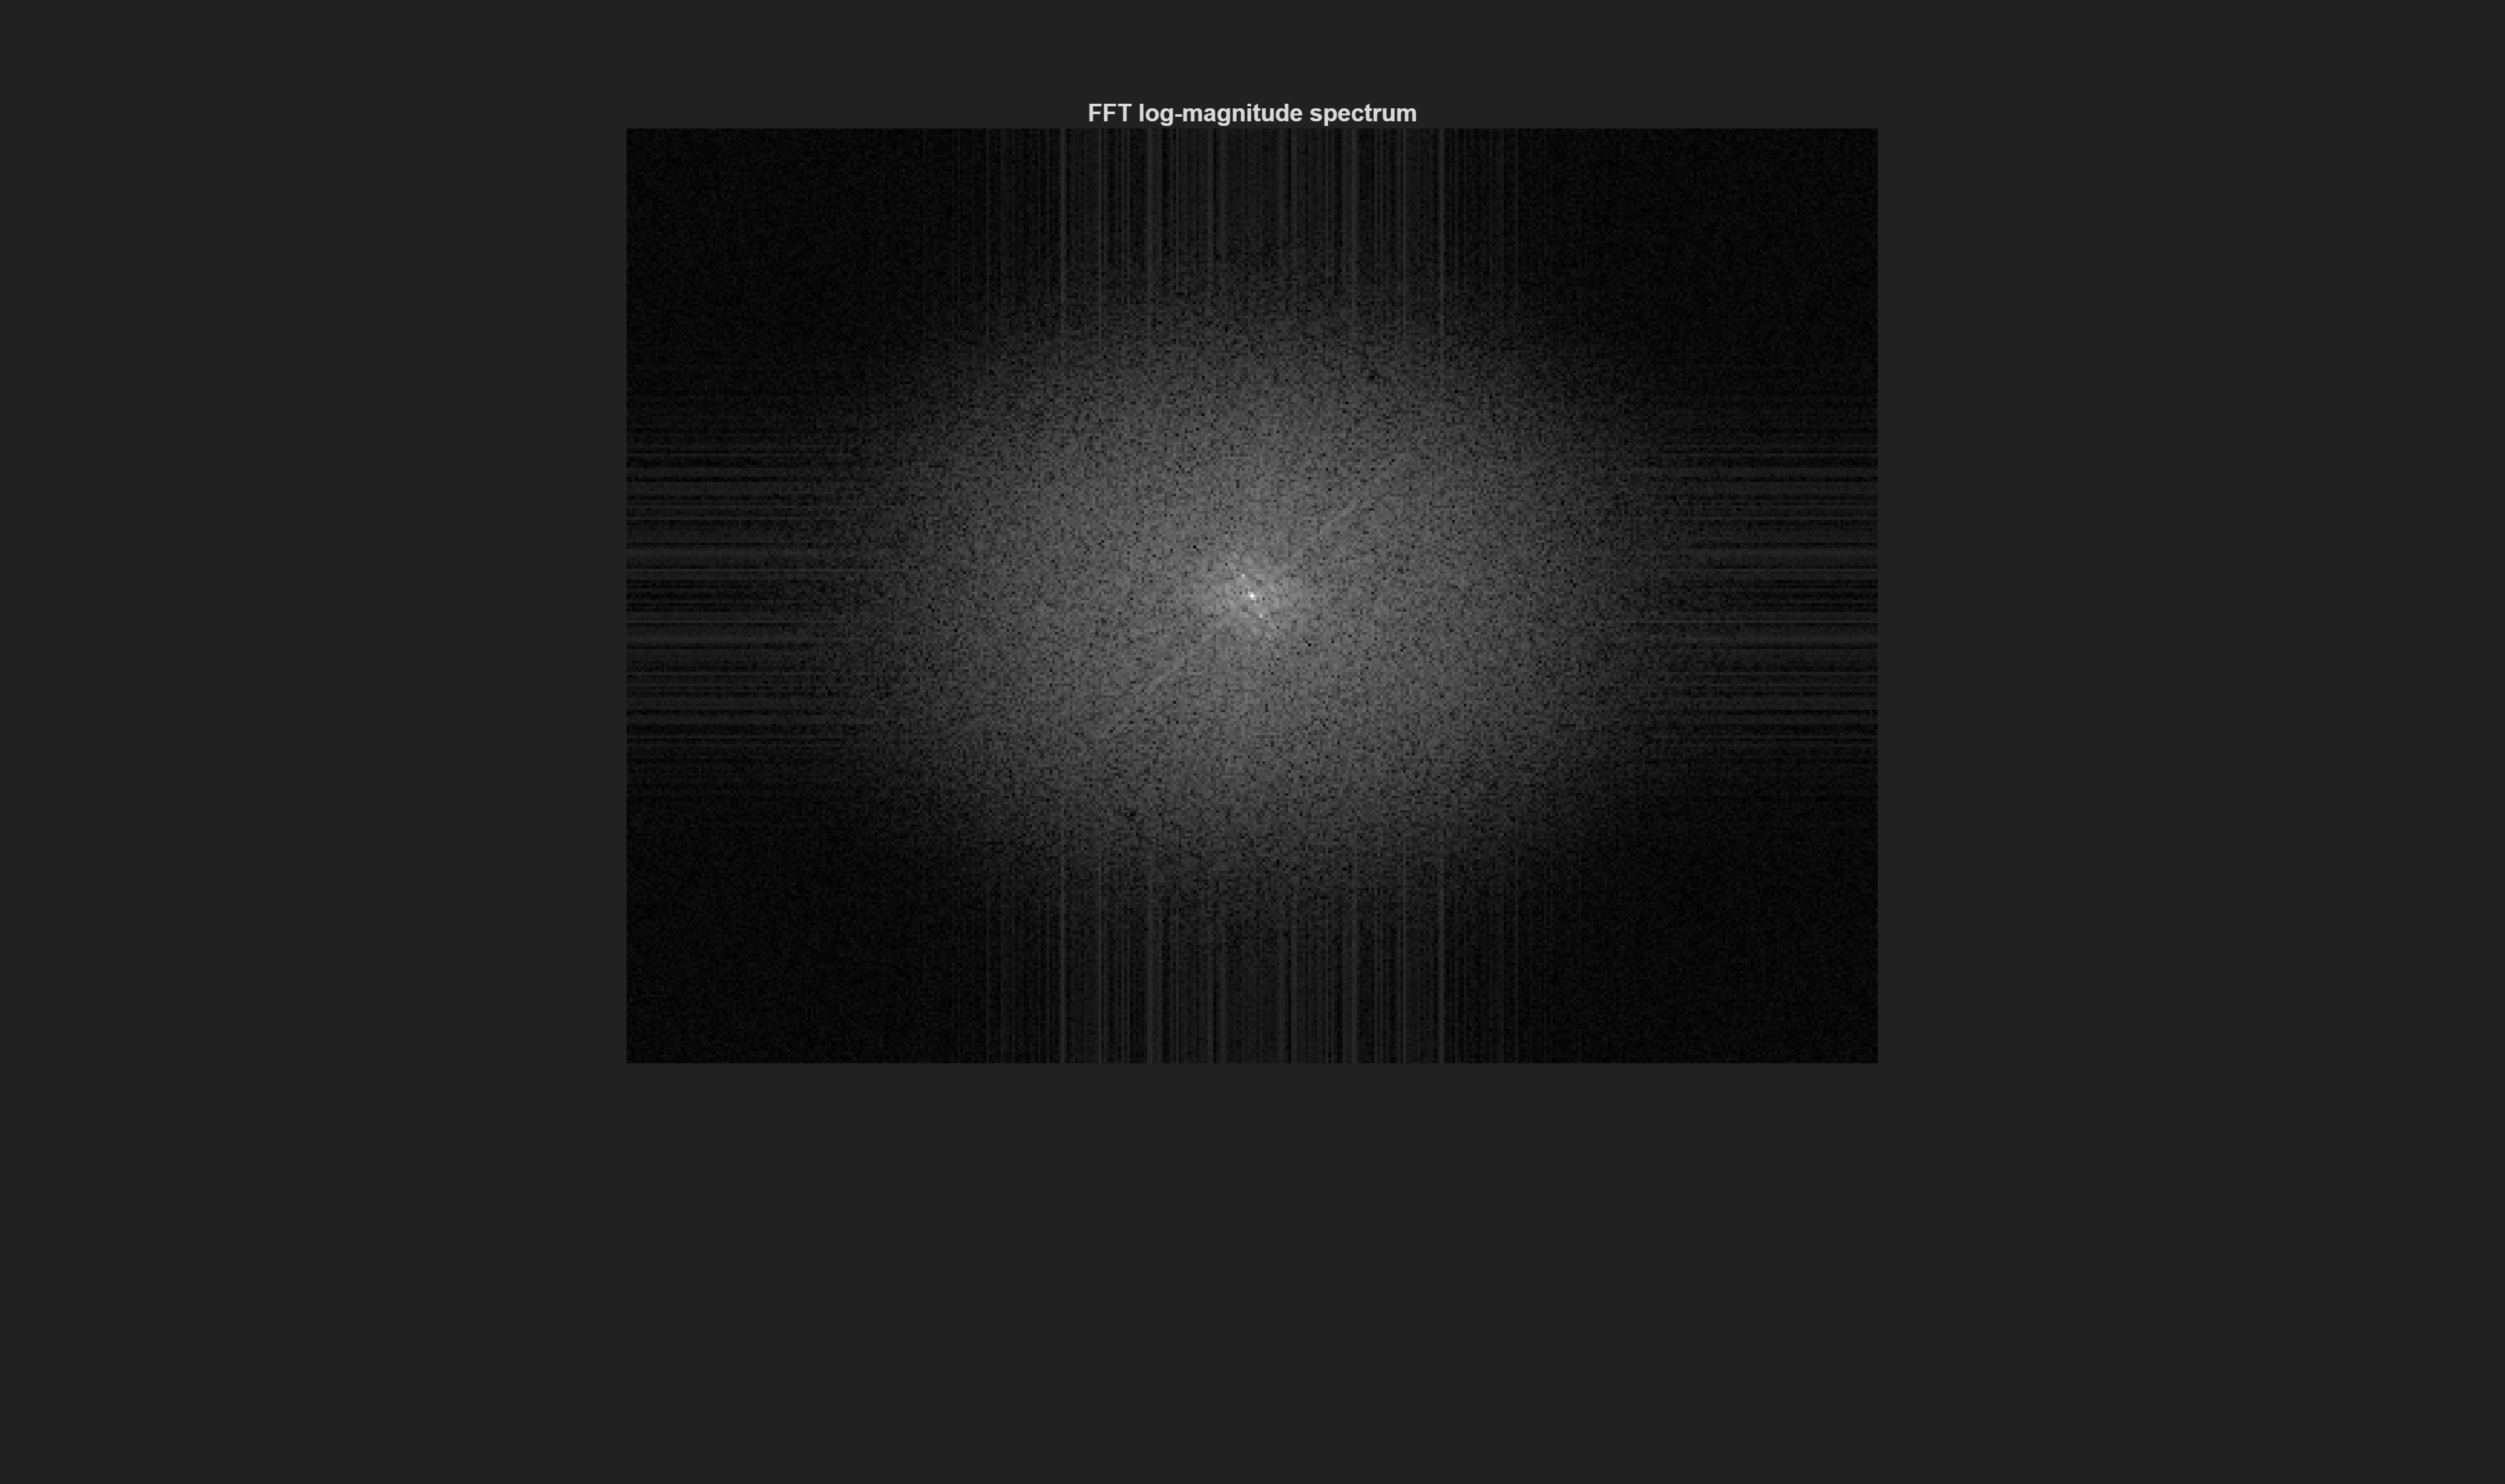

[xp, yp] = getpts;   % xp = columns, yp = rows

% 
% % Reject clicks too close to the center
% [M,N] = size(Ig);
% cx0 = N/2;  
% cy0 = M/2;
% 
% valid_idx = ( (xp - cx0).^2 + (yp - cy0).^2 > (min(M,N)/20)^2 );
% xp = xp(valid_idx);
% yp = yp(valid_idx);
% 
% if isempty(xp)
%     disp("All clicks were too close to DC component. Try again!");
% end



[M,N] = size(Ig);
[X,Y] = meshgrid(1:N,1:M);

% parameters to tune
sigma = 5;          % width of notch
strength = 0.1;    % 0 -> kill completely, 1 -> no filtering

filter_mask = ones(M,N);

for k = 1:length(xp)
    cx = xp(k); 
    cy = yp(k);

    % Gaussian notch
    G = exp(-((X-cx).^2 + (Y-cy).^2)/(2*sigma^2));
    G = 1 - (1-strength) * G;

    % symmetric peak
    cx2 = N - cx + 1;
    cy2 = M - cy + 1;

    G2 = exp(-((X-cx2).^2 + (Y-cy2).^2)/(2*sigma^2));
    G2 = 1 - (1-strength) * G2;

    filter_mask = filter_mask .* G .* G2;
end


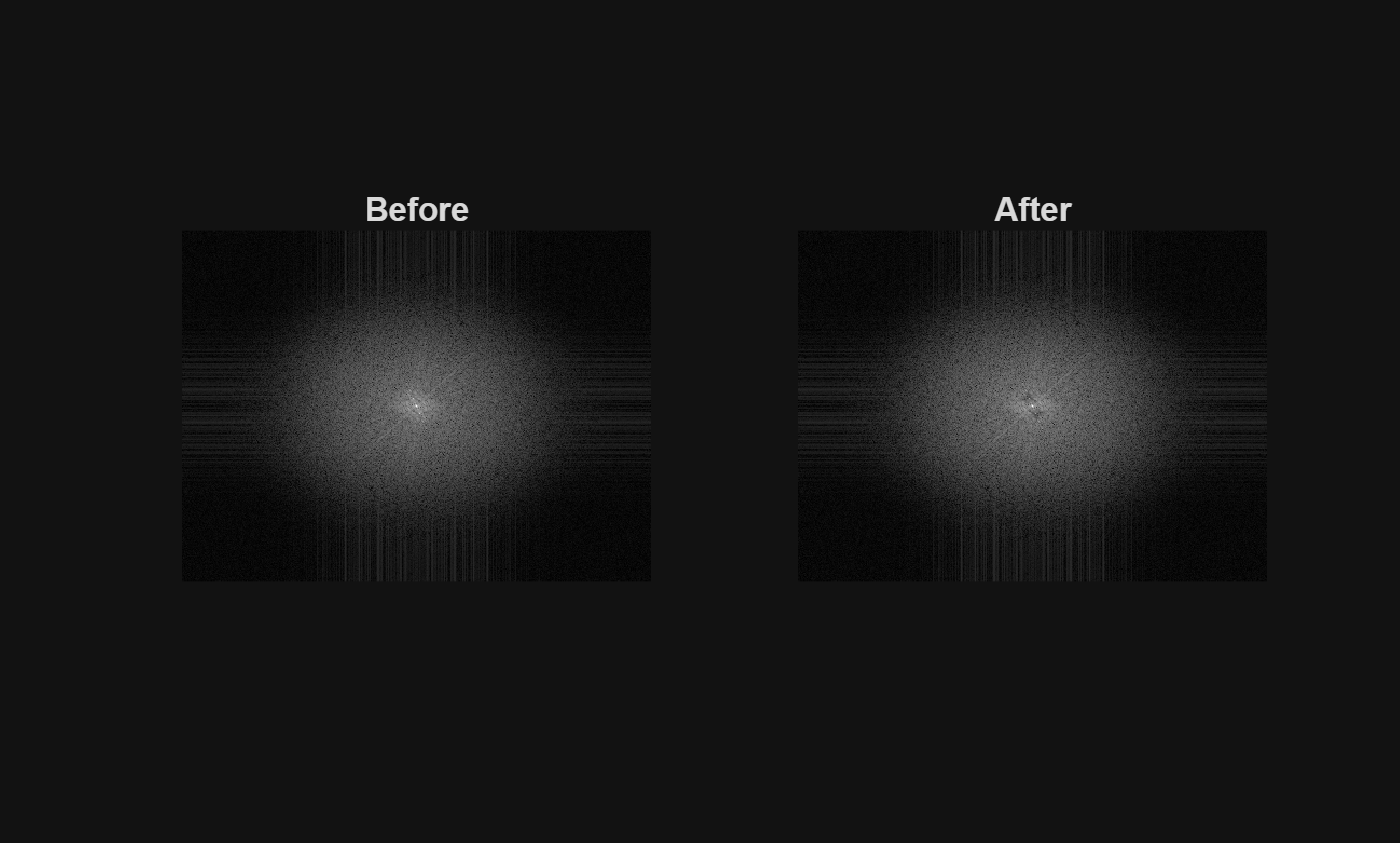

Ff = Fshift .* filter_mask;

spec_after = log(1 + abs(Ff));

figure; 
subplot(1,2,1); imshow(mat2gray(spec),[]); title("Before");
subplot(1,2,2); imshow(mat2gray(spec_after),[]); title("After");

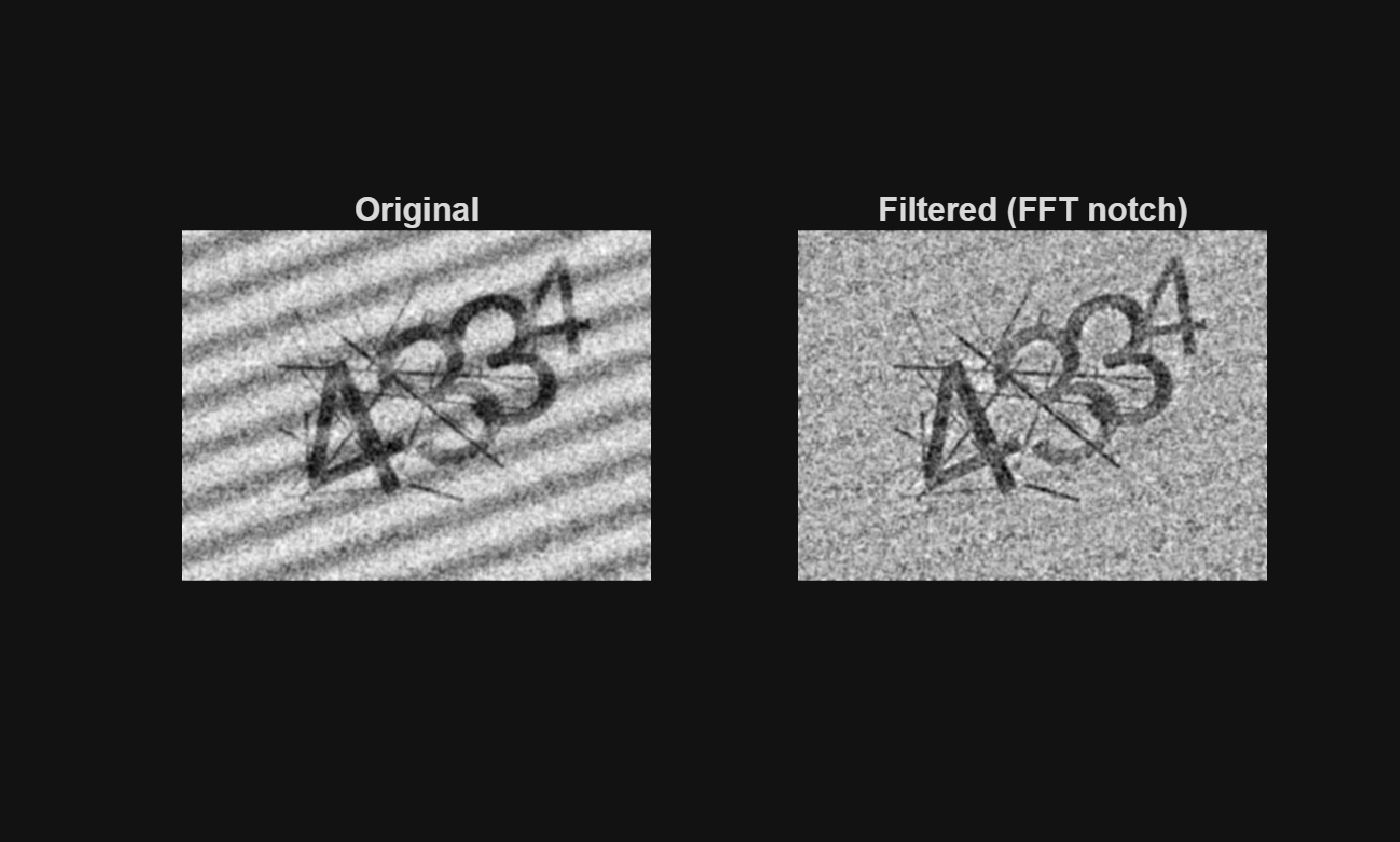

If = ifft2(ifftshift(Ff));
If = real(If);
If = mat2gray(If);

figure; 
subplot(1,2,1); imshow(Ig,[]); title("Original");
subplot(1,2,2); imshow(If,[]); title("Filtered (FFT notch)");

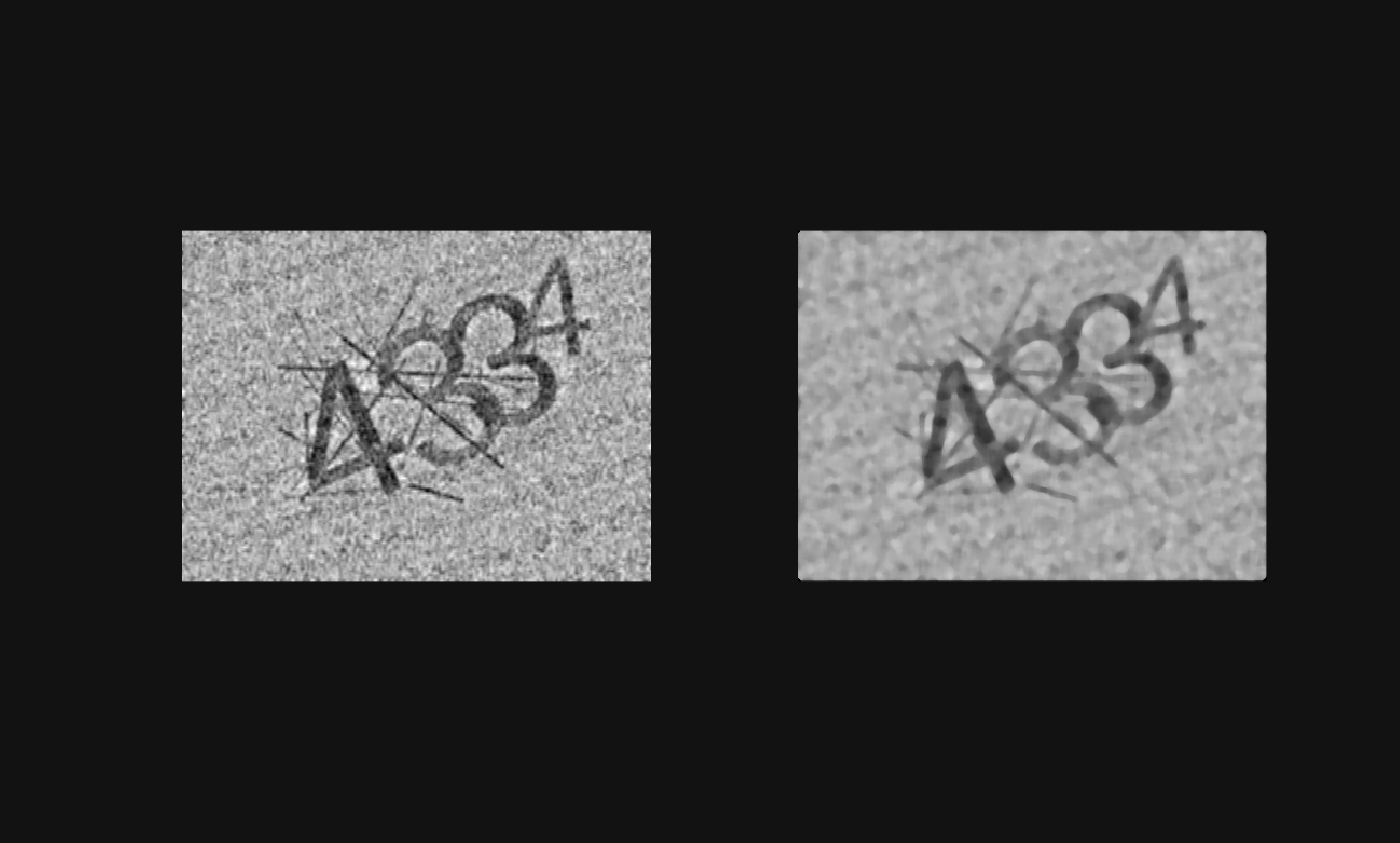

denoised = wdenoise(If , 3, 'Wavelet', 'db2', 'DenoisingMethod', 'Bayes');
denoisedl2 = medfilt2(denoised, [8 8]);   % try [5 5] for stronger effect
denoisedl3 = imgaussfilt(denoisedl2, 1.2);
figure;
subplot(1, 2, 1);
imshow(denoised);
subplot(1, 2, 2);
imshow(denoisedl2);

% subplot(1, 3, 3);
% imshow(denoisedl3);

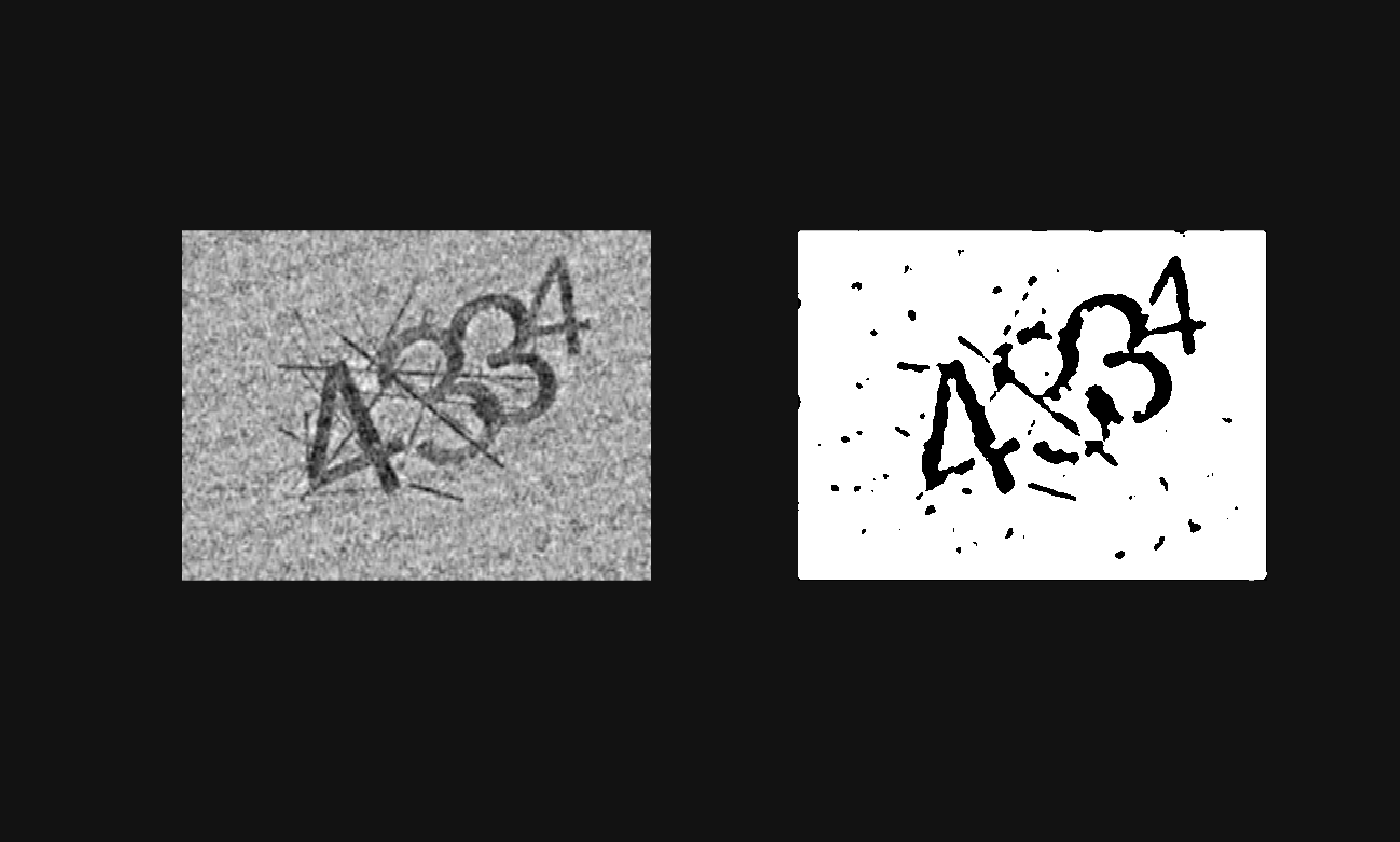

mask = imbinarize(denoisedl2, 'adaptive', ...
                  'ForegroundPolarity','dark', ...
                  'Sensitivity',0.45);   % adjust 0.40–0.70
imshow(mask);

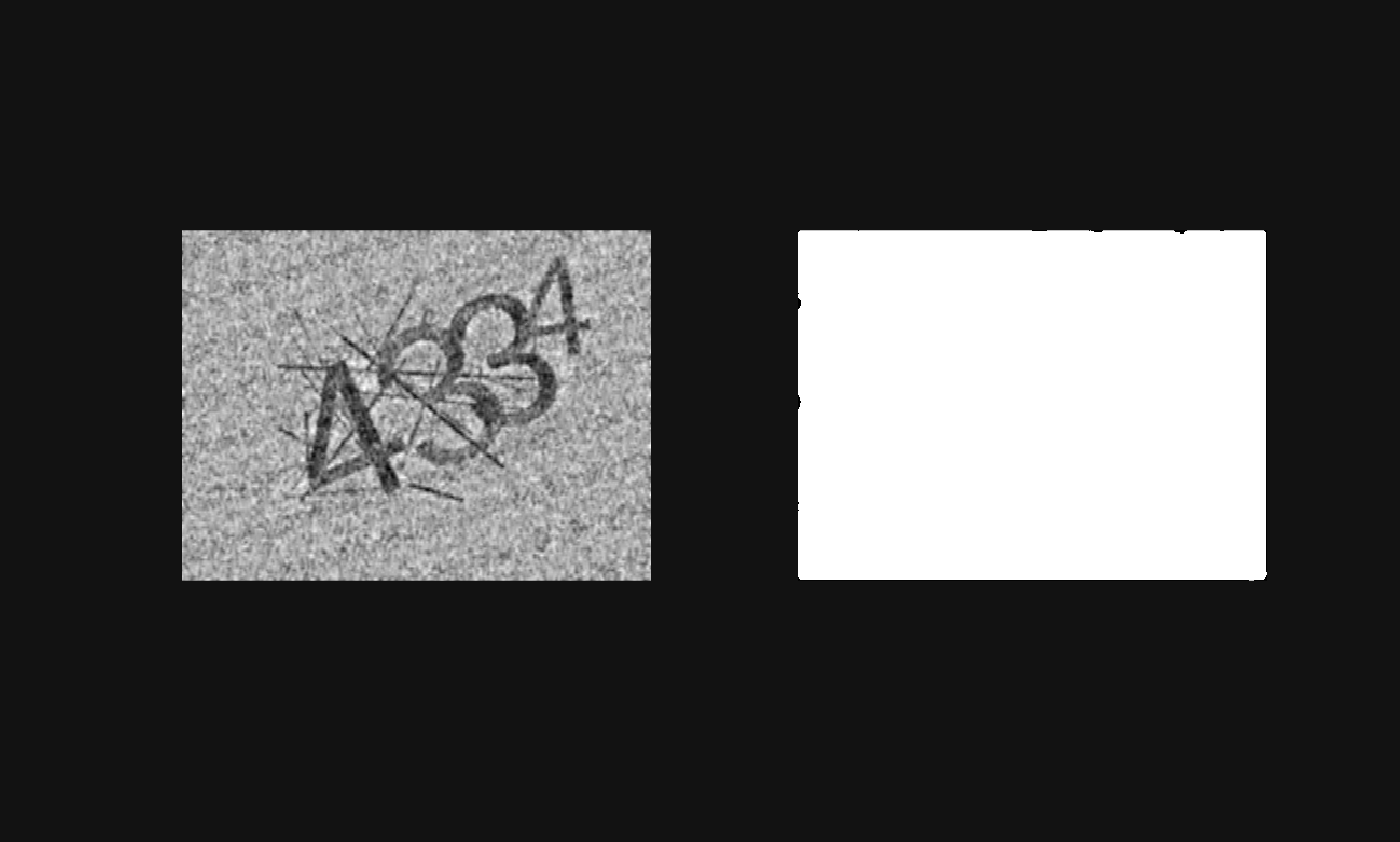

mask = bwareaopen(mask, 1);             % remove small dots
mask = imopen(mask, strel('disk', 2));  % connect broken strokes
mask = imfill(mask,'holes');             % fill digit interiors
imshow(mask);